### FIG 2d

K = 1;       
Omega = 50;
alpha = 2;
delta = 0.04;   

% minimum value thof 'a' for which the endemic equilibrium exists
a_crit = delta / (K * (Omega - 1));


r_min = 0.1; r_max = 2.0; N_r = 50; 
a_min = max(1e-4, a_crit * 0.5); 
a_max = 0.1; N_a = 1000;              

r_vals = linspace(r_min, r_max, N_r); 
a_vals = logspace(log10(a_min), log10(a_max), N_a); 


max_real_extinct = zeros(N_a, N_r);   % Maximum real part of eigenvalues at extinction equilibrium
max_real_endemic = NaN(N_a, N_r);     % Maximum real part of eigenvalues at endemic equilibrium


parfor i = 1:N_a
    a = a_vals(i);
    for j = 1:N_r
        r = r_vals(j);


        J_extinct = compute_jacobian(K, 0, 0, r, K, a, Omega, alpha, delta);
        eig_extinct = eig(J_extinct);
        max_real_extinct(i, j) = max(real(eig_extinct));

        if Omega > 1 && a > a_crit

            B_star = delta / (a * (Omega - 1));
            if B_star < K 
                numerator = r * (1 - B_star / K);
                denominator = a * (1 + (r * B_star) / (K * alpha));
                if denominator > 0 && numerator > 0
                    P_star = numerator / denominator;
                    I_star = (a * B_star * P_star) / alpha;

                    J_endemic = compute_jacobian(B_star, I_star, P_star, r, K, a, Omega, alpha, delta);
                    eig_endemic = eig(J_endemic);
                    max_real_endemic(i, j) = max(real(eig_endemic));
                end
            end
        end
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


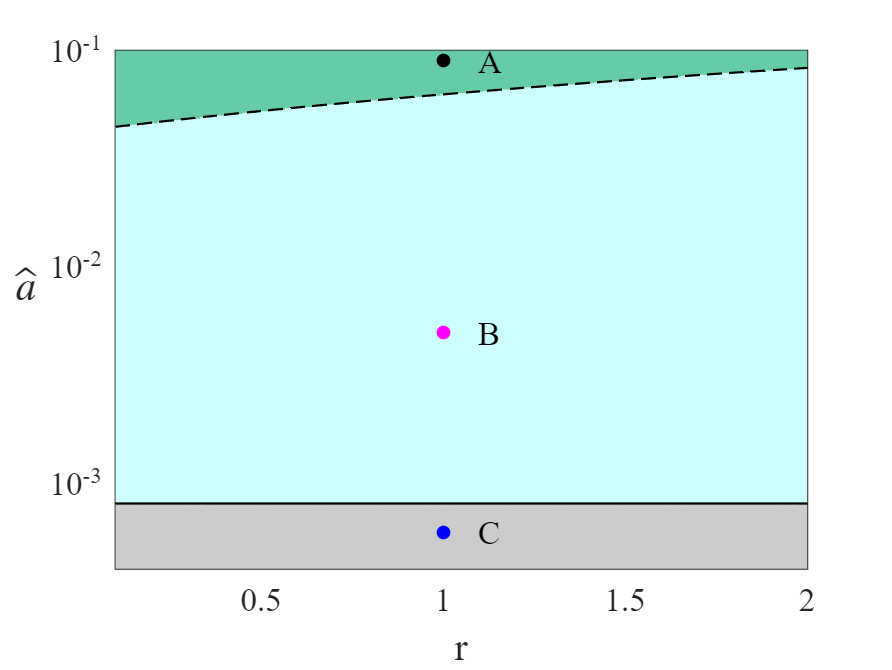


%% === Visualization ===
FontSize = 18;
points = [
    1,  0.09;     % 点1
    1,  0.005;    % 点2
    1,  0.0006    % 点3
];

labels = {'A', 'B', 'C'};
markers = {'o', 'o', 'o'};
colors_pts = {'k', 'm', 'b'};
-
figWidth_cm = 8;
figHeight_cm = 6;
dpi = 300; 
figWidth_px = figWidth_cm * dpi / 2.54;
figHeight_px = figHeight_cm * dpi / 2.54;

figure('Position', [100, 100, figWidth_px, figHeight_px]);
clf;

region = ones(N_a, N_r);
[aa, rr] = meshgrid(a_vals, r_vals);
aa = aa'; rr = rr';

valid_region = aa > a_crit;
stable_region = valid_region & (max_real_endemic < 0);
unstable_region = valid_region & (max_real_endemic > 0);

region(stable_region) = 2;
region(unstable_region) = 3;


colors_map = [
    0.8, 0.8, 0.8;   
    0.8, 1.0, 1.0;   
    0.4, 0.8, 0.66  
];

% pcolor
h = pcolor(r_vals, a_vals, region);
h.EdgeColor = 'none';
colormap(colors_map);
hold on;
caxis([0.5, 3.5]);

% --- bound ---
a_bound = a_crit * ones(size(r_vals));
plot(r_vals, a_bound, 'k-', 'LineWidth', 1.2);

contour(r_vals, a_vals, max_real_endemic, [0, 0], 'k--', 'LineWidth', 1.2);

for i = 1:size(points, 1)
    r_pt = points(i, 1);
    a_pt = points(i, 2);
    
    if r_pt >= r_min && r_pt <= r_max && a_pt >= a_min && a_pt <= a_max
        plot(r_pt, a_pt, ...
            'Marker', markers{i},'MarkerFaceColor', colors_pts{i},'Color', colors_pts{i}, ...
            'MarkerSize', 6, 'LineWidth', 1.5);
        
        text(r_pt + 0.05*(r_max - r_min), a_pt, labels{i}, ...
            'Color', 'black', ...
            'FontSize', FontSize, ...
            'FontName','Times New Roman',...
            'FontWeight', 'normal', ...
            'HorizontalAlignment', 'left', ...
            'VerticalAlignment', 'middle');
    end
end

ax = gca;
ax.FontName = 'Times New Roman';
ax.FontSize = FontSize;          
ax.LineWidth = 1;
xlim([r_vals(1), r_vals(end)]);
ylim([a_vals(1), a_vals(end)]);
xlabel('r', 'FontSize', FontSize+4, 'FontWeight', 'normal', 'Interpreter', 'tex');
ylabel('$\hat{a}$', 'FontSize', FontSize+4, 'FontWeight', 'normal', 'Interpreter', 'latex', ...
    'Rotation', 0, 'HorizontalAlignment', 'right');

set(ax, 'YScale', 'log');

hold off;


C = contourc(r_vals, a_vals, max_real_endemic, [0 0]);


r_boundary = [];
a_boundary = [];

if ~isempty(C)
    idx = 1;
    while idx < size(C, 2)
        numPoints = C(2, idx); % 当前段的点数
        segment_x = C(1, idx+1:idx+numPoints);
        segment_y = C(2, idx+1:idx+numPoints);
        r_boundary = [r_boundary; segment_x(:)];
        a_boundary = [a_boundary; segment_y(:)];
        idx = idx + numPoints + 1;
    end
end

%save('coexistence_stability_boundary.mat', 'r_boundary', 'a_boundary');


### FIG 2 a-c

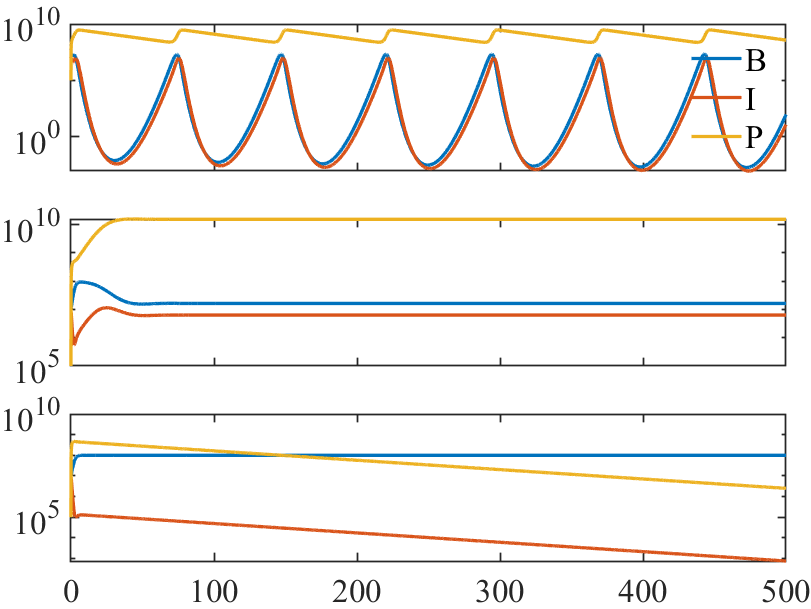

% parameter
r = 1;   
K = 1;  
a1 = 0.09;    
a2 = 0.005;
a3 = 0.0006;
Omega = 50;            
alpha = 2;
delta = 0.04;         


B0 = 0.1;     
I0 = 0.1;       
P0 = 0.001;    


tspan = [0 500];

y0 = [B0; I0; P0];

options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12,'MaxStep', 0.1);
[t1, y1] = ode15s(@(t,y) ode1B_nothre(t, y, r, K, a1, Omega,alpha, delta), tspan, y0, options);
tout1 = t1;
yout1 = y1*1e8;

[t2, y2] = ode15s(@(t,y) ode1B_nothre(t, y, r, K, a2, Omega,alpha, delta), tspan, y0, options);
tout2 = t2;
yout2 = y2*1e8;

[t3, y3] = ode15s(@(t,y) ode1B_nothre(t, y, r, K, a3, Omega,alpha, delta), tspan, y0, options);
tout3 = t3;
yout3 = y3*1e8;


% === Visualization ===
FontSize = 20;
figWidth_cm = 8;  
figHeight_cm = 6;
dpi = 300;
figure('Position', [100, 100, figWidth_cm*dpi/2.54, figHeight_cm*dpi/2.54]);


tl = tiledlayout(3, 1, 'Padding', 'none', 'TileSpacing', 'tight');


ax1 = nexttile;
semilogy(tout1, yout1(:,1:3), 'LineWidth', 2);

%ylim([10^0, 10^11]);
xlim(tspan);


lgd = legend('B','I','P');
lgd.Location = 'northeast';
lgd.FontSize = FontSize;
lgd.Box = 'off';


ax1.FontName = 'Times New Roman';
ax1.FontSize = FontSize;
ax1.LineWidth = 1;
ax1.XTickLabel = {}; 


ax2 = nexttile;
semilogy(tout2, yout2(:,1:3), 'LineWidth', 2);

%ylim([10^-1, 10^11]);
xlim(tspan);


ax2.FontName = 'Times New Roman';
ax2.FontSize = FontSize;
ax2.LineWidth = 1;

ax2.XTickLabel = {}; 


ax3 = nexttile;
semilogy(tout3, yout3(:,1:3), 'LineWidth', 2);
%ylim([10^0, 10^11]);
xlim(tspan);

ax3.FontName = 'Times New Roman';
ax3.FontSize = FontSize;
ax3.LineWidth = 1;

linkaxes([ax1, ax2, ax3], 'x');  

function J = compute_jacobian(B, I, P, r, K, a, Omega, alpha, delta)
    % Avoid division by zero error
    if B < 1e-9
        B = 1e-9;
    end
    if P < 1e-9
        P = 1e-9;
    end
    
    J11 = r * (1 - (B + I)/K) - r*B/K - a*P;
    J12 = -r * B / K;
    J13 = -a * B;
    
    J21 = a * P;
    J22 = -alpha;
    J23 = a * B;
    
    J31 = -a * P;
    J32 = Omega * alpha;
    J33 = -a * B - delta;
    
    J = [J11, J12, J13; 
         J21, J22, J23; 
         J31, J32, J33];
end